## Results

angles = linspace(30, 60, 60);
speeds = linspace(9.5, 11.5, 600);

makes = nan(600, 60);

for angle = 1:60
    for speed = 1:600
        makes(speed, angle) = determine_make(speeds(speed), angles(angle));
    end
end

gaussKernel = fspecial('gaussian', 3, 2);

'fspecial' requires Image Processing Toolbox.

makes_smooth = conv2(makes, gaussKernel,'same');

clf; figure; hold on;
contourf(angles, speeds, makes_smooth, [0 1])
map = [1 0 0; 0 1 0];
colormap(map)
title('Makes vs misses')
xlabel('Launch Angle')
ylabel('Launch Velocity (m/s)')

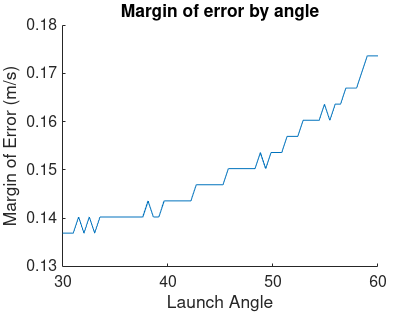

[angles, moes] = sweep_angle_moe();
figure; clf; hold on;
plot(angles, moes)
title('Margin of error by angle')
xlabel('Launch Angle')
ylabel('Margin of Error (m/s)')

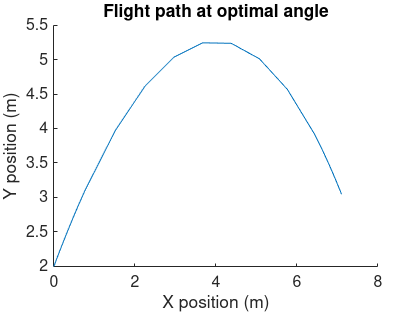

 [T, U] = bball_trajectory(10, 57.45);
 figure; clf; hold on;
 plot(U(:, 1), U(:, 2))
 title('Flight path at optimal angle')
 xlabel('X position (m)')
 ylabel('Y position (m)')